# Princeton MVPA toolbox tutorial

## Reference

This tutorial compiles information from several posts from the original toolbox Wiki, including

- [Setup](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/wiki/Setup)

- [TutorialIntro](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/wiki/TutorialIntro)

- [TutorialIntroSPM](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/wiki/TutorialIntroSPM)

- [Manual](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/wiki/Manual)

- [Reference Datasets](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/releases/tag/data-sets)

in order to provide a walkthrough of the lab session on multivariate pattern analysis (MVPA) on 2/20/2022. 

You may also want to check out these two tutorials on

- [MVPA and RSA concepts](https://dibsmethodsmeetings.github.io/multivariate-pattern-analysis/), and

- [MATLAB basics](https://dibsmethodsmeetings.github.io/matlab-basics/).

## Setup

- Connect to Dukeblue wifi or [vpn.duke.edu](https://vpn.duke.edu/).

- Login to the [NI server](https://dibs-niserv.ccn.duke.edu:3300/auth/) (instructions at "NI_server_login" in Sakai).

- Copy `/share/data/class/fmri22/labs/week6` to `/share/data/class/fmri22/students/<your name>`

- Click on Activities, click on the 9 dots to see all apps, then open MATLAB.

- Open `tutorial.m` in MATLAB.

- For all commands, feel free to save them in the MATLAB script for your own record.

% housekeeping
clear         % remove all stored variables
close all     % close all open windows (e.g., figures)
clc           % clean up the command window

- Note that the present working directory of MATLAB is `/home/<netid>`.

- Change your working directory to `/share/data/class/fmri22/students/<your name>/week6` by doing one of the following

-         paste `/share/data/class/fmri22/students/<your name>/week6` into the address bar on

- `    cd /share/data/class/fmri22/students/<your name>/`

- `    cd('/share/data/class/fmri22/students/<your name>/week6')`

% cd('/share/data/class/fmri22/students/shenyang/week6') % server
cd('C:\OneDrive - Duke University\Duke\Research\Resources\princeton-mvpa-toolbox') % local

Error using cd
Unable to change current folder to 'C:\OneDrive - Duke University\Duke\Research\Resources\princeton-mvpa-toolbox' (Name is nonexistent or not a folder).

- Confirm your present working directory by typing `pwd` in the Command Window.

- Check that you have these files in `nifti_set/working_set/`

-         `structural.nii`

-         `mask_cat_select_vt.nii`

-         `haxby8_r*.nii`

-         `tutorial_regs.mat`

-         `tutorial_runs.mat`

- save the relative path to data with 

data_dir = 'nifti_set/working_set/';

## Install the toolbox

The `princeton-mvpa-toolbox` has already been downloaded into `/share/apps/princeton-mvpa-toolbox-master`. Note that we are using an [adapted version](https://github.com/Huang-Shenyang/princeton-mvpa-toolbox/) of the [original toolbox](https://github.com/PrincetonUniversity/princeton-mvpa-toolbox/) to solve errors in overloading MATLAB functions.

Add the toolbox to MATLAB's path by doing one of the following

- Home -> Set Path -> Add Folder -> add the toolbox directory

- Use command: `addpath /share/apps/princeton-mvpa-toolbox-master`

% addpath /share/apps/princeton-mvpa-toolbox-master % server
addpath('C:\OneDrive - Duke University\Duke\Research\Resources\princeton-mvpa-toolbox\') % local

Call `mvpa_add_paths` to add relevant subfolders to path.

mvpa_add_paths()

Now we are all set up for using the Princeton MVPA Toolbox in MATLAB.

## Introduction

This tutorial will run through the basics of a single within-subject analysis, classifying fMRI brain states into different conditions using the multi-voxel pattern analysis (MVPA) methods.

We will use a single subject's data from the [Haxby et al. (2001)](https://www.science.org/doi/10.1126/science.1063736), in which the subject viewed lots of exemplars of 8 different types of images. The 8 categories are: face, house, cat, bottle, scissors, shoe, chair, and scrambled images.

Each run contained a 9-TR block for each condition with rest in between and at either end. There are 10 runs of a single subject included in the dataset in this toolbox. 

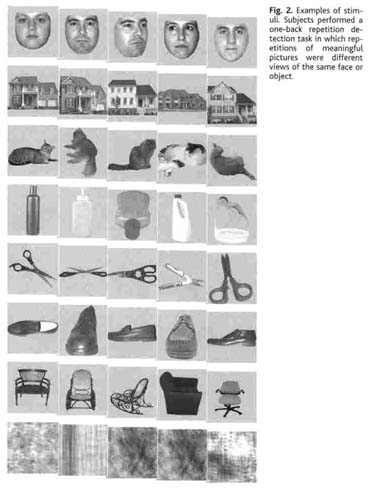

The goal of the analysis is to classify the distributed patterns of neural activity in order to predict psychological states (e.g., viewing a face) from the neural state from a certain brain region (e.g., BOLD pattern in ventral temporal cortex).

Original quote from the tutorial:

*"We called this document *`tutorial_easy.htm`*. Don't let that fool you. We've really done everything we can to trip you up with it. Just wait till you try TutorialAdv. It's so difficult and scary that small children will cry around the globe whenever a copy is downloaded. In the meantime, let us begin."*

### Outline of MVPA

The goal of this analysis is to teach a classifier to predict which class of object the subject is viewing on each trial. To do this, we need several bits of information:

- a `pattern` to classify, which is BOLD data from (part of) the brian

- a set of `regressors`, which is a matrix of condition labels that identify each volume/frame/TR in the data. This is necessary for training the classifier.

- a `selector`. When dealing with classifiers, one cannot train and test the classifier on the same data. Doing so would lead to artificially inflated accuracy. So we will need a set of selectors that indicate which timepoints should be used for testing and which should be used for training.

- a `mask`, which is a 3D boolean/binary matrix that labels the voxels we want to keep in the `pattern`.

## Load data into MATLAB

### Initializing the subject structure

This toolbox uses a single monolithic structure to house all of these types of information for an individual subject. As this is the main structure for each subject, we'll call it the `subj` structure.

Our analysis will begin by creating a subject structure, and loading the patterns, selectors, regressors, and masks we need. Later, we will run the actual analysis by passing the subject structure to the classifier and supporting functions.

To initialize it for use with the toolbox, we need to specify what we're going to call the experiment ('haxby8') and a unique identifier for the subject ('tutorial_subject'):

help init_subj


init_subj not found.

Use the Help browser search field to search the documentation, or
type "help help" for help command options, such as help for methods.



subj = init_subj('haxby8', 'tutorial_subj');

Unrecognized function or variable 'init_subj'.

summarize(subj)

Eventually, you will have more and more objects in your structure of each type as you go through the steps of data processing and analysis.

### Load ventral temporal GLM mask

#### **Task 1**

- **Using fsleyes, overlay the mask 'VT_category-selective' on the structural image provided and take a screenshot.**

- **Explain the purpose of this mask in terms of the research question and if you see any issues with using this mask.**

Now load the mask to MATLAB with the following function, while replacing the field enclosed in <>: 

- `subj = load_spm_mask(subj, <what we want to call this mask>, <path to mask file>);`

subj = load_spm_mask(subj, 'VT_category-selective', [data_dir 'mask_cat_select_vt.nii']);

*Note: this mask happens to be an anatomically-defined ventral temporal mask that has already had a GLM applied to further restrict the voxels. We're using this just to whittle down the number of voxels so that the tutorial runs quickly, but it isn't really scientifically legitimate because it is peeking into the data before classification. For a real analysis, you'd want to create your masks without peeking.*

To see how the `subj` structure looks now that the mask object has been added:

summarize(subj)

### Load fMRI data

Use a `for` loop to iterate over the 10 functional files and save their file names:

for i=1:10
    raw_filenames{i} = [data_dir 'haxby8_r' num2str(i) '.nii']; 
end

Use `load_spm_pattern` to read values from the functional files, but only save those values within the mask we already selected. We will call them the saved pattern 'epi'. 

subj = load_spm_pattern(subj, 'epi', 'VT_category-selective', raw_filenames);

#### **Task 2**

- **In the output of **`summarize(subj)`**, what is Patterns-'epi'?**

- **What does the 577 x 1210 matrix contain? Explain the information by looking at each row and at each column.**

summarize(subj)
% if you want to probe into how MATLAB stores the activation values, look here
subj.patterns{1}

### Label the functional data

This original toolbox refers to what we call labels **condition regressors**, which provide information about the conditions each TR belongs to--just like the regressors matrix that a GLM would use.

That information is stored in 'tutorial_regs.mat' as a variable named `regs`. Let us load the variable into MATLAB and fill that into the `subj` structure.

subj = init_object(subj, 'regressors', 'conds');
load([data_dir 'tutorial_regs.mat']);
subj = set_mat(subj, 'regressors', 'conds', regs);
condnames = {'face', 'house', 'cat', 'bottle', 'scissors', 'shoe', 'chair', 'scramble'};
subj = set_objfield(subj, 'regressors', 'conds', 'condnames', condnames);

#### **Task 3**

- **Look at the conditions by either looking into the **`regs`** variable or in MATLAB workspace or visualize it using **`imagesc(regs); colorbar;`**.**

- **Take a screenshot of the variable or figure and explain what you can tell about the task structure.**

% code section


### Task run information

We need to know which scanning session each TR comes from, as that information is crucial for setting up the classifier. The run information is stored in 'tutorial_runs.mat' as a variable named `runs`. Let us load the variable into MATLAB and fill that into the `subj` structure.

subj = init_object(subj, 'selector', 'runs');
load([data_dir 'tutorial_runs.mat']);
subj = set_mat(subj,'selector', 'runs', runs);

You should see that it contains 10*121 integer labels, one for each TR, identifying which scanning run that TR came from.

## Pre-classification processing

### Z-scoring

It helps to z-score the data by subtracting out the mean of each voxel's timecourse and scaling it so that the standard deviation of the timecourse is one. 

`zscore_runs.m` treats each run as a separate timecourse, which can help remove any between run differences due to baseline shifts. It takes in the name of the pattern you want to z-score ('epi'), and also the selector name that contains the runs information ('runs'), so that it knows how to z-score each run separately.

subj = zscore_runs(subj, 'epi', 'runs');

To confirm z-scoring is done properly, examine this scatter plot

voxel_to_plot = 271;
timecourse_raw = subj.patterns{1}.mat(voxel_to_plot, :)';
timecourse_z = subj.patterns{2}.mat(voxel_to_plot, :)';

figure; 
scatter(timecourse_raw, timecourse_z);
title(['z-scored timecourse against raw timecourse for voxel ' num2str(voxel_to_plot)]);

### Creating the cross-validation indices

To conduct cross-validation, we partition the data into n parts, and train n different classifiers, each with n-1 parts used for training and the left-out 1 part as testing data.

subj_TRselector = create_xvalid_indices(subj, 'runs');

Examine the new selectors

summarize(subj_TRselector, 'objtype', 'selector');
% code section


#### Task 4

- **Explain what is plotted in this figure and why we need this variable.**

figure; 
selector_to_plot = 1;
imagesc(subj_TRselector.selectors{selector_to_plot}.mat); 
colorbar;
title(['plotting selector ' num2str(selector_to_plot)]);
% code section


For each of the 10 new selectors, we see a bunch of '2's and '1's in `subj_TRselector.selectors{x}.mat`. In those arrays, '1's signify TRs that will be used as training data for the classifier for this iteration. These '1' TRs will also be used for feature selection later. The '2's label the testing data TRs and will be ignored in feature selection to avoid peeking.

### Feature selection

Before actually doing the classification, it usually helps to throw away uninformative voxels.

The easiest way is to use ANOVA to yield a p-value: the probability of observing data at least as extreme as the observed data given that a given voxel's activity between conditions is the same.

Note that this ANOVA method runs completely separately for each voxel.

subj_fs_05 = feature_select(subj_TRselector, 'epi_z', 'conds', 'runs_xval');

This creates 10 additional masks, each corresponding to one ANOVA.

summarize(subj_fs_05,'objtype','mask')

#### Task 5

The default p-value threshold is 0.05, but wen can also change that.

subj_fs_thres = feature_select(subj_TRselector, 'epi_z', 'conds', 'runs_xval', 'thresh', 0.00001);
summarize(subj_fs_thres, 'objtype', 'mask')

- **Pick a lower p-value threshold than 0.05. How many voxels on average are included in each of the newly generated masks?**

- **Do you think this feature selection step removed more/fewer voxels than you would expect? Why? (Hint: look at the section on loaing the VT mask.)**

## Leave-one-run-out cross-validation classification

The code below demonstrates how to call a simple backpropogation neural network to perform classification of the conditions based on neural activity in selected voxels.

% use a backpropogation neural network classifier
clf = 'bp'; 
class_args.train_funct_name = ['train_' clf]; 
class_args.test_funct_name = ['test_' clf];
class_args.nHidden = 0; % number of hidden layers in bp neural network

In case you are interested, the Princeton MVPA toolbox also provides other types of classifiers, like logistic regression and support vector machine (SVM). 

% clf = 'logreg'; % logistic regression
% clf = 'ridge'; % ridge regression
% class_args.penalty = 20; % parameter for logistic regression and ridge regression to penalize small weights

% clf = 'svm'; % Though theoretically SVM can classify multiple categories, this implementation cannot. 
% class_args.kernel_type = 2; % kernel for SVM which doesn't work here

Now let us actually run cross-validation classification.

[subj_fs_05, results_fs_05] = cross_validation(subj_fs_05, 'epi_z', 'conds', 'runs_xval', 'epi_z_thresh0.05', class_args);

In the output, `results_fs_05.total_perf` tells us the overall proportion of the time that the classifier guessed correctly on its testing TRs (averaged across all 10 iterations).

The classification performance will be different each time you run the program because backprop randomly initializes its weights each time it is run.

### Warning: Not 1-of-n regressors

Note that we're getting this warning

for each iteration, which indicates that for some TRs the regressor/condition is not ONE of the desired ones--could be multiple or zero.

We can check how many condition labels each TR has this way:

figure; 

subplot(2,1,1)
imagesc(regs); 
colorbar;
title('8 regressors on each TR');

subplot(2,1,2)
imagesc(sum(regs)); 
colorbar;
title('Sum of regressors on each TR');

Apparently, the toolbox creators deliberately left the rest TRs in the tutorial dataset, which should be excluded from MVPA. So we will do that.

### Remove rest TRs using selectors

% identify rest TRs
temp_sel = zeros(1, size(regs,2));
temp_sel(sum(regs)==1) = 1;

% create a new 'no_rest' selector object
subj_TRselector_norest = init_object(subj, 'selector', 'no_rest');
subj_TRselector_norest = set_mat(subj_TRselector_norest, 'selector', 'no_rest', temp_sel);
subj_TRselector_norest = create_xvalid_indices(subj_TRselector_norest, 'runs', 'actives_selname', 'no_rest');

Before we do anything else, let us confirm that the rest TRs are indeed excluded from the new selector. 

regs_norest = regs(:, logical(temp_sel));

figure; 

subplot(2,1,1)
imagesc(regs_norest); 
colorbar;
title('8 regressors on each task TR');

subplot(2,1,2)
imagesc(sum(regs_norest)); 
colorbar;
title('Sum of regressors on each task TR');

Repeat feature selection and classification with task TRs only

% feature selection
subj_norest_fs_05 = feature_select(subj_TRselector_norest, 'epi_z', 'conds', 'runs_xval');
% use a backpropogation neural network classifier
clf = 'bp'; 
class_args.train_funct_name = ['train_' clf]; 
class_args.test_funct_name = ['test_' clf];
% parameters for the classifier chosen
class_args.nHidden = 0; % number of hidden layers in bp neural network

% classification
[subj_norest_fs_05, results_norest_fs_05] = cross_validation(subj_norest_fs_05, 'epi_z', 'conds', 'runs_xval', 'epi_z_thresh0.05', class_args);

Voila! No warnings this time, and we see a huge boost in the classification accuracy in each of the iterations.

#### Task 6

- **Why does classification accuracy improve when we exclude rest TRs?**

results_fs_05.total_perf
results_norest_fs_05.total_perf

## Concluding remarks

Again, quoting from the original toolbox wiki:

*"Congratulations on completing this tutorial. Now you know enough to be dangerous. Play with your data for a bit, and then try TutorialAdv which builds on all these concepts and introduces further procedures for the kinds of things that you'll probably want to try before too long."*

*"For instance, we aren't convolving our regressors with a haemodynamic response function to take account of the lag in the BOLD response - this is a pretty critical omission."*